**1. Considere a função Matlab string2hash() que implementa duas funções de dispersão diferentes.**

**Utilizando separadamente cada uma destas funções de dispersão, simule a inserção das chaves criadas**

**em 6.1 em 3 Chaining Hash Tables, uma de tamanho 5 × 10^5, outra de tamanho 10^6 e a terceira de**

**tamanho 2 × 10^6. Para cada uma das simulações:**

function chaves_geradas = gerar_chaves(chaves_a_gerar, imin, imax, caracteres, prob_characteres)
    if nargin < 5
        % Se o último parâmetro não for fornecido, assume probabilidades iguais
        prob_characteres = ones(1, length(caracteres)) / length(caracteres);
    end
    
    chaves_geradas = cell(1, chaves_a_gerar);
    
    for i = 1:chaves_a_gerar
        % Gerar comprimento aleatório da chave entre imin e imax
        comprimento = randi([imin, imax]);
        
        % Gerar chave com base nas probabilidades
        chave = randsample(caracteres, comprimento, true, prob_characteres);
        
        % Converter vetor para string e armazenar no cell array
        chaves_geradas{i} = char(chave);
    end
end

function hash=string2hash(str,type)
    str=double(str);
    if(nargin<2), type='djb2'; 
    end
    switch(type)
        case 'djb2'
            hash = 5381*ones(size(str,1),1); 
            for i=1:size(str,2) 
                hash = mod(hash * 33 + str(:,i), 2^32-1); 
            end
        case 'sdbm'
            hash = zeros(size(str,1),1);
            for i=1:size(str,2) 
                hash = mod(hash * 65599 + str(:,i), 2^32-1);
            end
        otherwise
            error('string_hash:inputs','unknown type');
    end
end

N = 1e5;
imin = 6;
imax = 20;
caracteres = ['A':'Z', 'a':'z'];
prob_characteres = [];

chaves_geradas = gerar_chaves(N, imin, imax, caracteres, prob_characteres)

chaves_geradas = 1×100000 cell array
  Columns 1 through 1599

    {'UHcWjApy'}    {'EJjmOsPYMCfwaRBr'}    {'eeNnypQgR'}    {'GiHbrkVX'}    {'MSjIZoYnpLiC'}    {'MrYIkkkFCJvMsh'}    {'GATNfxddUgsNMQoS'}    {'hjkJYVHgcwDSPDYa'}    {'qkpIjwmQhujEDCnRB'}    {'uRooPaTZuYDw'}    {'chcQNVivvCYzrZaZx'}    {'HrETPdvb'}    {'PMdjIwmmdInk'}    {'zmUoCJZttjteip'}    {'kRNTyOjCwKZhDxjm…'}    {'xqeTWbI'}    {'orbmJvNdb'}    {'BPRzNemukhxjtAf'}    {'xsmpHj'}    {'wHKtWlts'}    {'MyFQefdSxh'}    {'OrWfEpZnzYjUFaNmk'}    {'QrFgrSmZGQTXES'}    {'OjTvRe'}    {'mTlceuYT'}    {'iEHcaJQ'}    {'GxlZairWvEqPZauxT'}    {'BqLdoIqYGuZn'}    {'OAgBAnspuzXCH'}    {'jcApGEtZWE'}    {'uDJAhyqiHTptPZuK'}    {'sxLnWChMGg'}    {'kOPIkC'}    {'YIvHiaIorbAXnXqT…'}    {'OWymkqehNgriiNJ'}    {'SHiSUoEvcdfkzxKY…'}    {'CyqaGlElawHQt'}    {'dPCfbjdw'}    {'TowbuPFgXc'}    {'HcRxwpxYOtINmVoU…'}    {'sNaUUjulvngWwhoZP'}    {'DwHaxxnjshiPG'}    {'ZVNSPprIxYCSXZBD…'}    {'ikEtJqQxnh'}    {'YFclJZmleQHwXQTi…'}    {'ysFKPcaUOIsZf

**(a)** Guarde um vetor com os hashcodes obtidos.

hashcode_djb2 = zeros(1,size(chaves_geradas, 2));
hashcode_sdbm = zeros(1,size(chaves_geradas, 2));


for i = 1:size(chaves_geradas, 2)
    hashcode_djb2(i) = string2hash(chaves_geradas{i}, 'djb2');
    hashcode_sdbm(i) = string2hash(chaves_geradas{i}, 'sdbm');
end

disp('HashCodes das chaves geradas (com djb2):')

HashCodes das chaves geradas (com djb2):


hashcode_djb2

hashcode_djb2 = 1.0e+09 *

    2.1702    3.8993    2.6555    1.1380    0.9699    2.8779    1.0231    0.4228    0.1926    1.4742    3.3700    3.7048    2.1519    1.3985    3.7902    0.6705    0.6777    3.2807    0.6738    2.8878    3.5954    2.5294    2.4235    3.3526    1.4947    1.0175    0.2366    3.0145    2.6979    3.0462    2.9641    0.4392    0.1212    2.2667    2.6416    1.4699    1.6932    2.0038    3.7356    1.5258    3.0106    3.1370    0.4572    1.1473    2.5596    0.4191    3.6148    1.0705    2.7266    1.8400



disp('HashCodes das chaves geradas (com sdbm):')

HashCodes das chaves geradas (com sdbm):


hashcode_sdbm

hashcode_sdbm = 1.0e+09 *

    1.1834    0.1863    2.5506    1.2928    1.2519    0.6858    2.4100    1.1377    3.9362    1.9024    0.6521    3.7204    1.4211    2.9294    0.2596    2.5674    2.9423    3.4914    0.5313    3.0414    1.8611    1.6269    1.5178    3.2754    2.0993    4.1521    3.3544    1.3186    2.5285    1.7535    1.4569    1.4121    0.3478    3.8796    0.4449    2.4353    3.9810    3.0835    0.0438    3.2285    0.1329    3.3698    0.7016    2.9873    3.5822    4.0768    1.2369    2.4447    2.2213    0.3244


**(b)** Registe o número de atribuições a cada uma das posições de cada Hash Table.

hashtable1_djb2 = zeros(1,5e5);
hashtable2_djb2 = zeros(1, 1e6);
hashtable3_djb2 = zeros(1, 2e6);

hashtable1_sdbm = zeros(1,5e5);
hashtable2_sdbm = zeros(1, 1e6);
hashtable3_sdbm = zeros(1, 2e6);

for i = 1:size(hashcode_djb2, 2)
    hashtable1_djb2_index = mod(hashcode_djb2(i), 5e5);
    hashtable2_djb2_index = mod(hashcode_djb2(i), 1e6);
    hashtable3_djb2_index = mod(hashcode_djb2(i), 2e6);

    hashtable1_sdbm_index = mod(hashcode_sdbm(i), 5e5);
    hashtable2_sdbm_index = mod(hashcode_sdbm(i), 1e6);
    hashtable3_sdbm_index = mod(hashcode_sdbm(i), 2e6);

    hashtable1_djb2(hashtable1_djb2_index) = hashtable1_djb2(hashtable1_djb2_index) + 1;
    hashtable2_djb2(hashtable2_djb2_index) = hashtable2_djb2(hashtable2_djb2_index) + 1;
    hashtable3_djb2(hashtable3_djb2_index) = hashtable3_djb2(hashtable3_djb2_index) + 1;

    hashtable1_sdbm(hashtable1_sdbm_index) = hashtable1_sdbm(hashtable1_sdbm_index) + 1;
    hashtable2_sdbm(hashtable2_sdbm_index) = hashtable2_sdbm(hashtable2_sdbm_index) + 1;
    hashtable3_sdbm(hashtable3_sdbm_index) = hashtable3_sdbm(hashtable3_sdbm_index) + 1;
end

**(c)** Calcule o número de colisões (em cada Hash Table e para cada função de dispersão).

hashtable1_djb2_collisions = 0;
hashtable2_djb2_collisions = 0;
hashtable3_djb2_collisions = 0;

hashtable1_sdbm_collisions = 0;
hashtable2_sdbm_collisions = 0;
hashtable3_sdbm_collisions = 0;

for i = 1:5e5
    if hashtable1_djb2(i) > 1
        hashtable1_djb2_collisions = hashtable1_djb2_collisions + 1;
    end

    if hashtable1_sdbm(i) > 1
        hashtable1_sdbm_collisions = hashtable1_sdbm_collisions + 1;
    end
end

for i = 1:1e6
    if hashtable2_djb2(i) > 1
        hashtable2_djb2_collisions = hashtable2_djb2_collisions + 1;
    end

    if hashtable2_sdbm(i) > 1
        hashtable2_sdbm_collisions = hashtable2_sdbm_collisions + 1;
    end
end

for i = 1:2e6
    if hashtable3_djb2(i) > 1
        hashtable3_djb2_collisions = hashtable3_djb2_collisions + 1;
    end 

    if hashtable3_sdbm(i) > 1
        hashtable3_sdbm_collisions = hashtable3_sdbm_collisions + 1;
    end
end

hashtable1_djb2_collisions

hashtable1_djb2_collisions = 8697

hashtable2_djb2_collisions

hashtable2_djb2_collisions = 4665

hashtable3_djb2_collisions

hashtable3_djb2_collisions = 2409


hashtable1_sdbm_collisions

hashtable1_sdbm_collisions = 8707

hashtable2_sdbm_collisions

hashtable2_sdbm_collisions = 4617

hashtable3_sdbm_collisions

hashtable3_sdbm_collisions = 2402


djb2_collisions = hashtable1_djb2_collisions + hashtable2_djb2_collisions + hashtable3_djb2_collisions

djb2_collisions = 15771

sdbm_collisions = hashtable1_sdbm_collisions + hashtable2_sdbm_collisions + hashtable3_sdbm_collisions

sdbm_collisions = 15726

**2. Utilizando a informação obtida no exercício anterior, compare o desempenho das funções de dispersão**

**para cada tamanho diferente da Hash Table, relativamente a:**

**(a)** Uniformidade, visualizando os histogramas dos hascodes com 100 intervalos;

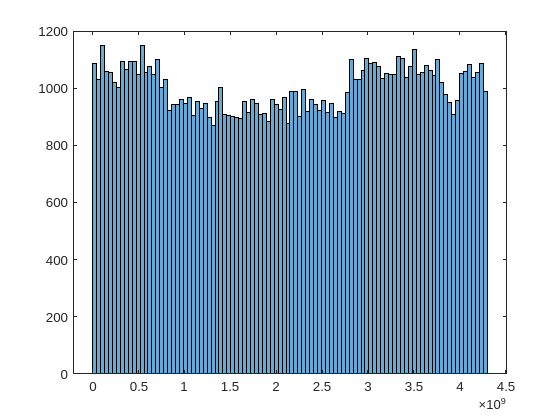

histogram(hashcode_djb2, 100)

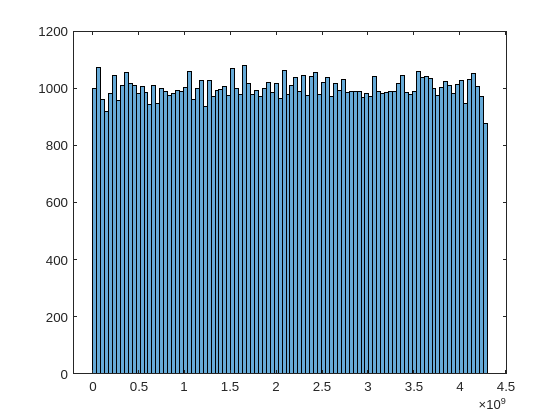


histogram(hashcode_sdbm, 100)

**(b)** Número de colisões e número máximo de atribuições numa mesma posição da Hash Table.

hashtable1_djb2_max_attributions = max(hashtable1_djb2)

hashtable1_djb2_max_attributions = 4

hashtable2_djb2_max_attributions = max(hashtable2_djb2)

hashtable2_djb2_max_attributions = 4

hashtable3_djb2_max_attributions = max(hashtable3_djb2)

hashtable3_djb2_max_attributions = 3


hashtable1_sdbm_max_attributions = max(hashtable1_sdbm)

hashtable1_sdbm_max_attributions = 5

hashtable2_sdbm_max_attributions = max(hashtable2_sdbm)

hashtable2_sdbm_max_attributions = 5

hashtable3_sdbm_max_attributions = max(hashtable3_sdbm)

hashtable3_sdbm_max_attributions = 3